clearvars -except kg kg2 rkg k out

# **kg2 fish cleaner**

## multi plotter

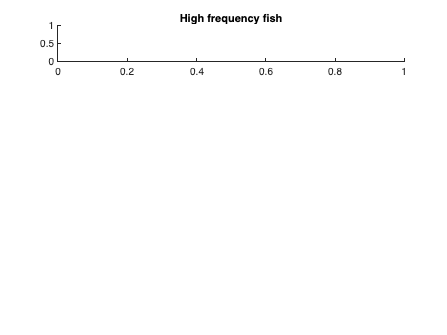

Dot indexing is not supported for variables of this type.

Error in k_multifishplotter (line 48)
        plot([out.hifish(ttohi).timcont]/3600, [out.hifish(ttohi).obwAmp],'.', 'Color', teal); 

k_multifishplotter(kg2(k));

hi = kg2(k).hical;
lo = kg2(k).local;

k = 13;

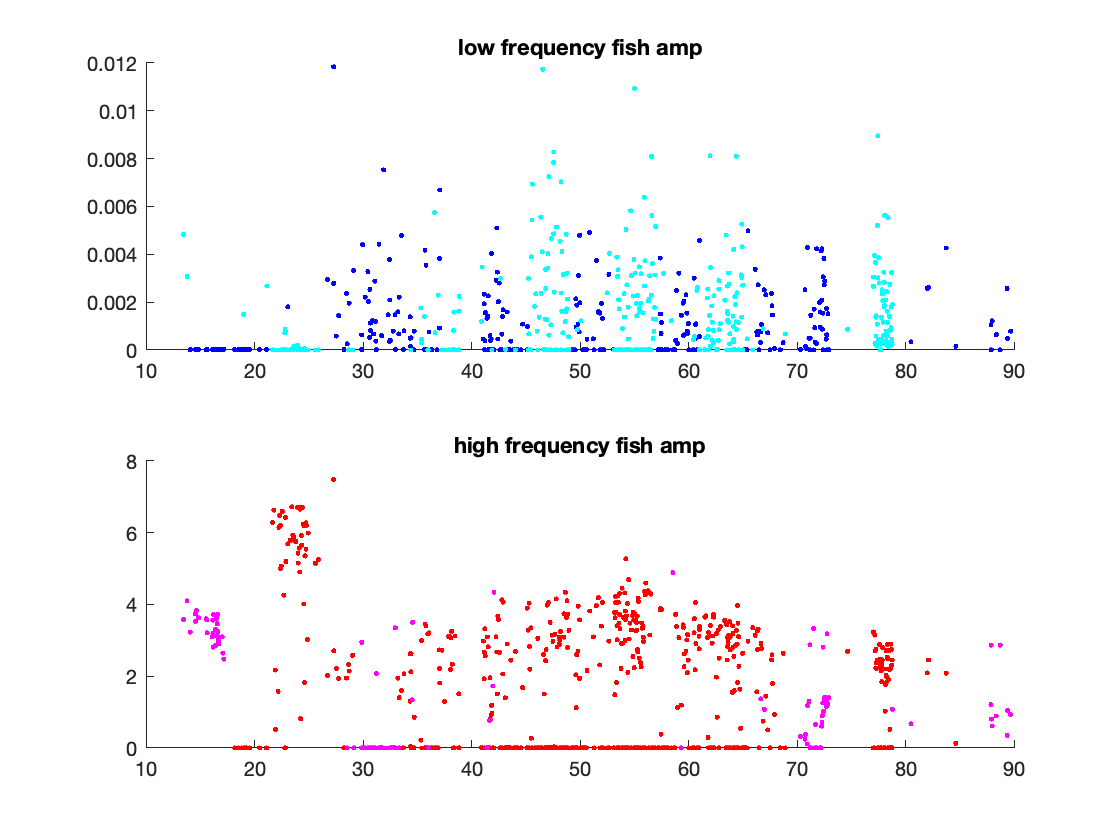

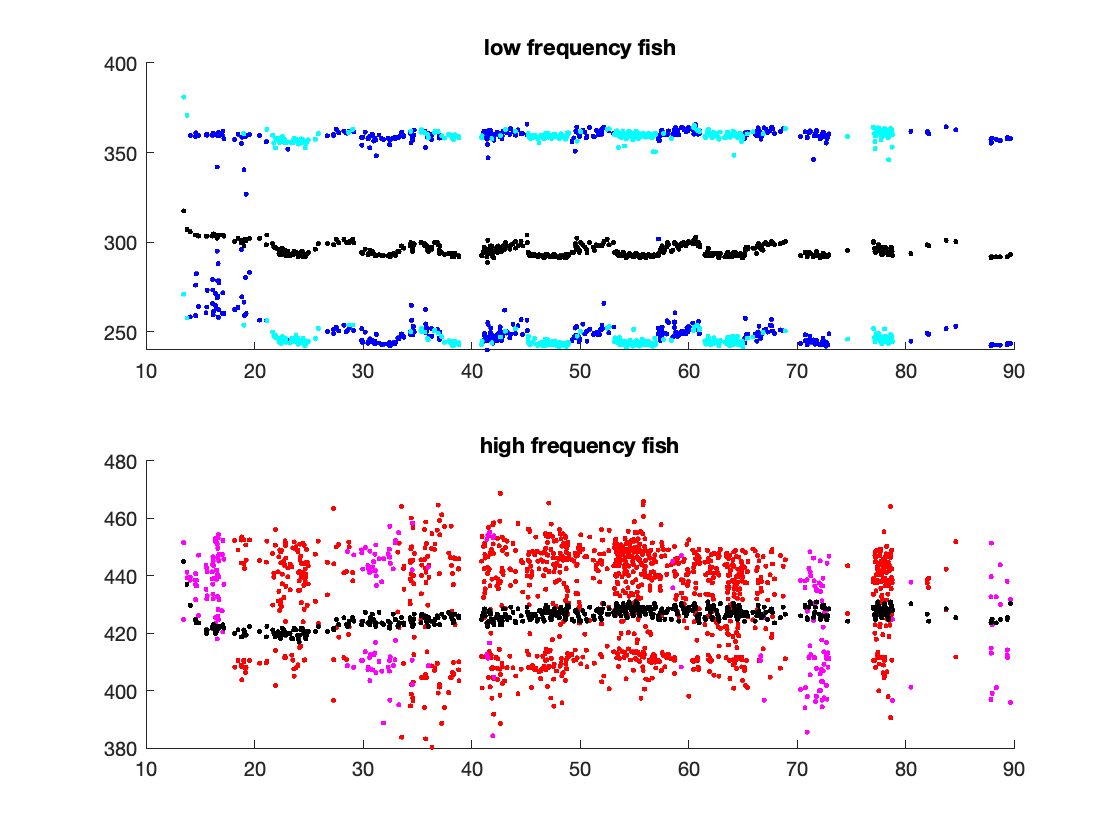

kg2(k).os = AnxiouslySeparatedobwAmp(kg2(k));

#### Plot unmodified amplitude data

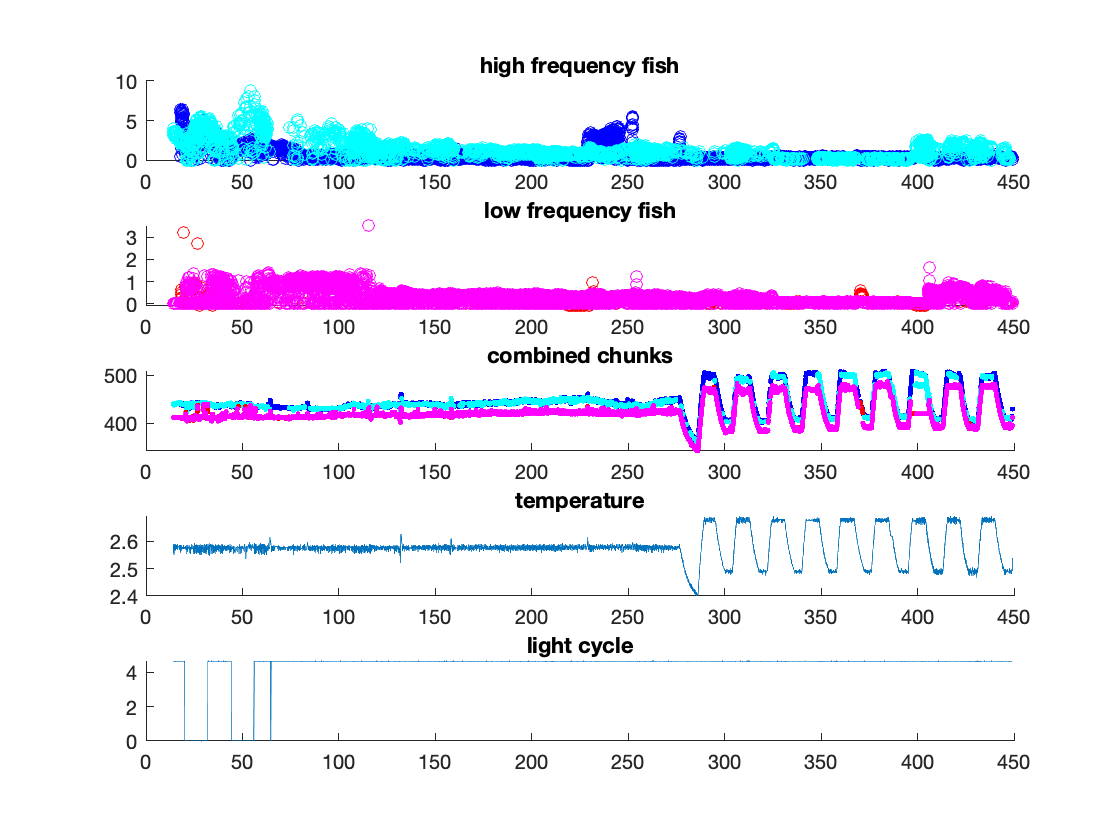

k_peakampmultiplotter(kg2(k).s);%, kg2(k).os);

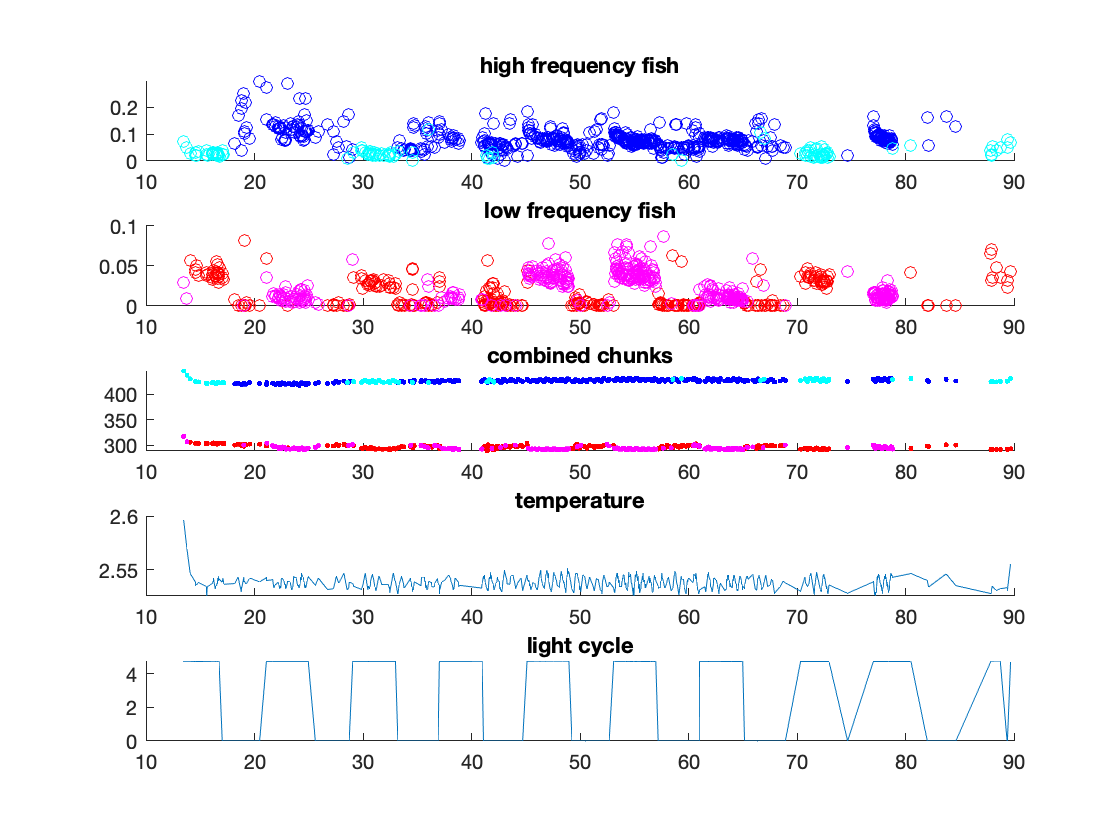

k_obwampmultiplotter(kg2(k).s, kg2(k).os);

#### trim

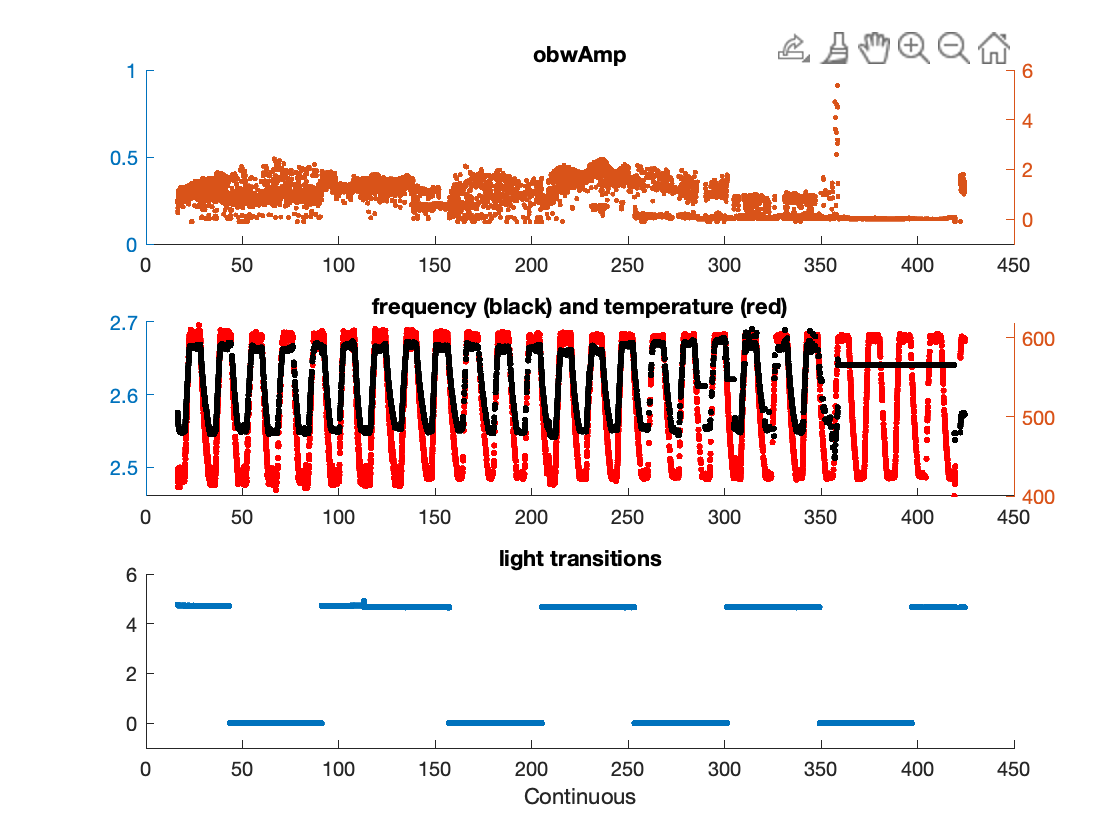

 tempdata  = KatieMultiTrimmer(kg2(k).s);

if before was on purpose 

kg2(k).s = tempdata;

#### Filter fish frequency errors

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.


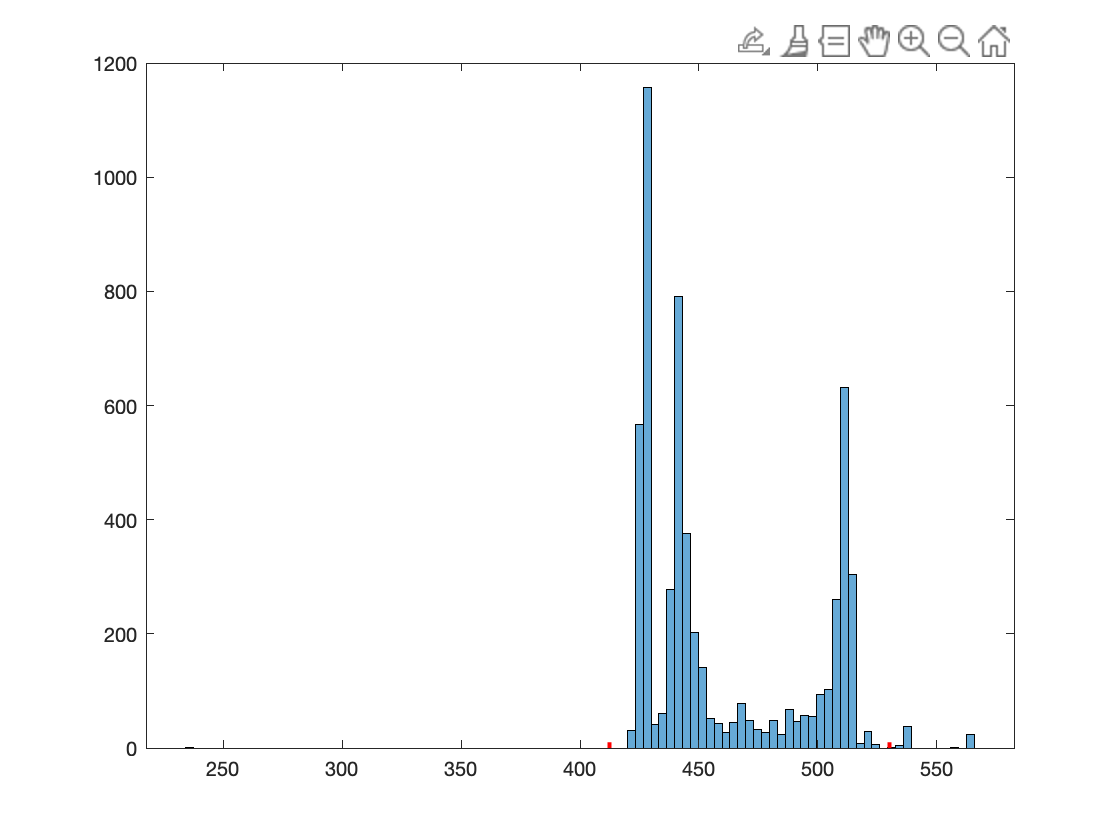

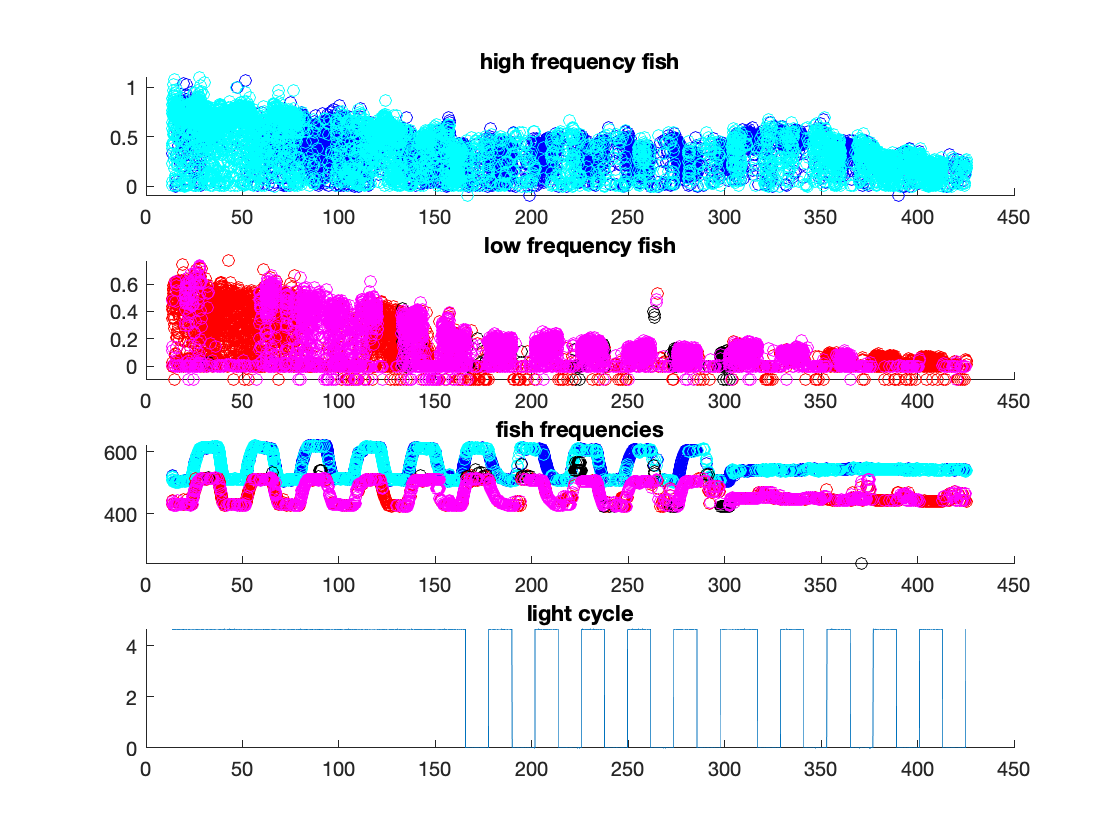

[hi, lo] = k_multifishfreqtrim(kg2(k).s);%, kg2(k).os);

hibackup = hi;
lobackup = lo;


for those times we fuck up but don't want to reclick frequency

 hi = hibackup;
% lo = lobackup;

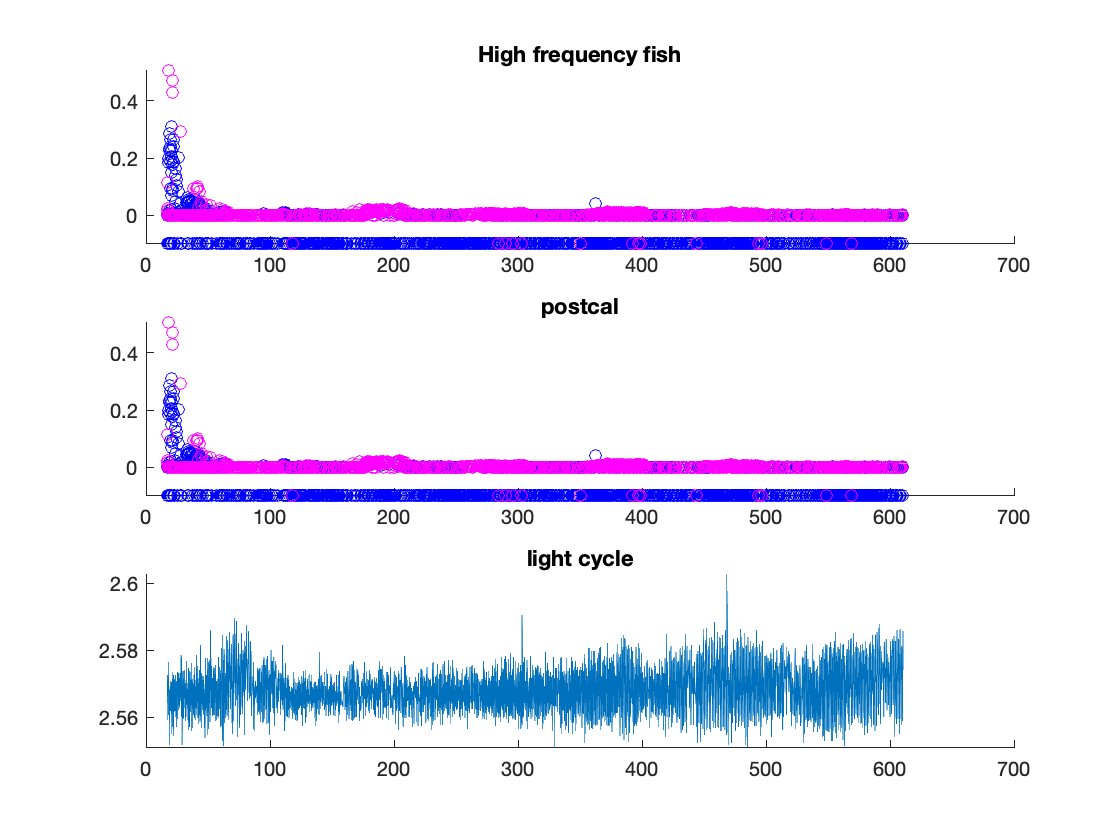

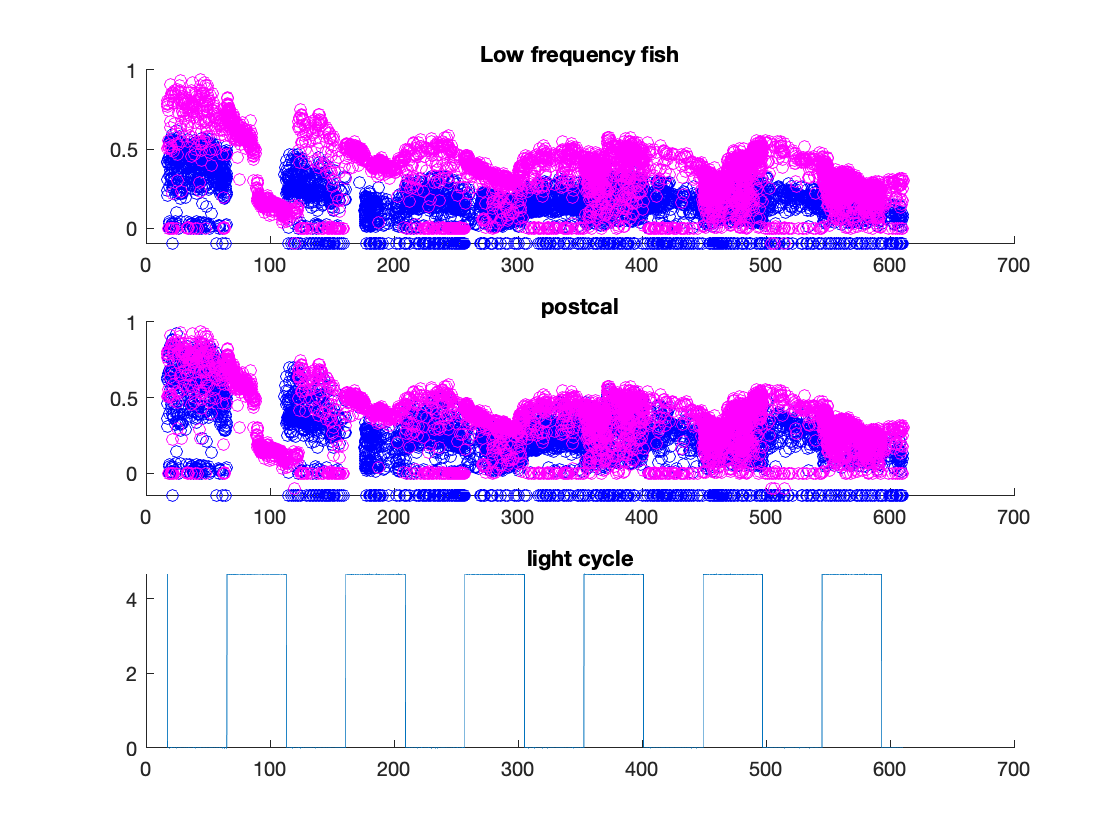

k_fishcalplotter(hi, lo, kg2(k).s);

## Hi frequency fish

tube = 1;

 hi(tube).obwamp =  hi(tube).obwamp;
 

#### save newly calibrated data into output structure

% sout = KatieFinalfishsplit(in)
kg2(k).hifish = KatieFinalfishsplit(hi);
kg2(k).hical = hi;

%outlier removal
%low amplitude data means fish was not inside tube during recording
kg2(k).hiidx = KatiesingleMultiRemover(kg2(k).hifish);

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.


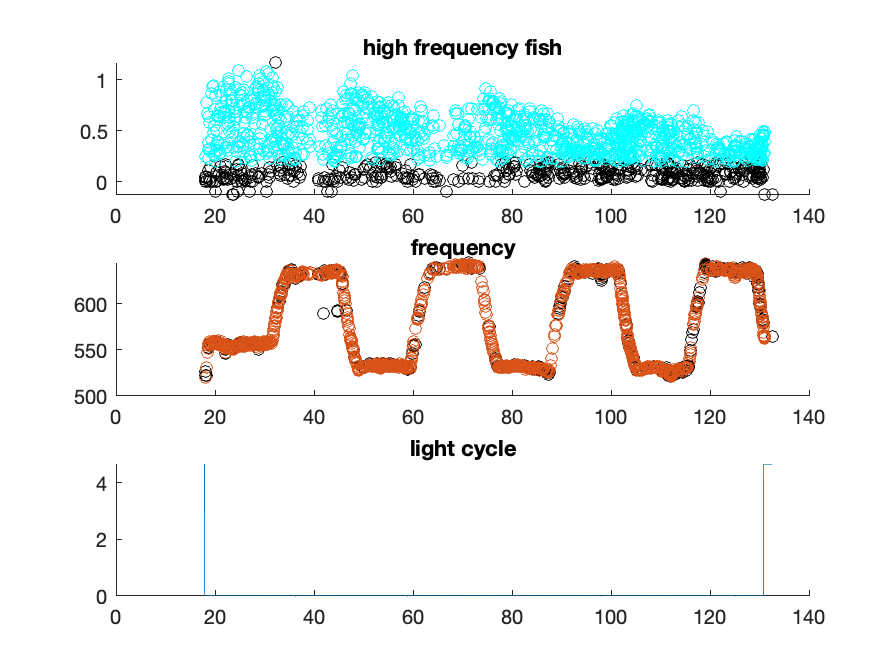

%plot to check
k_removercheckplot(6, kg2(k)); 

%normalize to max value after removal
kg2(k).himaxval = k_normcheckplot(6, kg2(k));
%mostly just checks 

## Low frequency fish

k_fishcalplotter(lo, kg2(k).s, 'low frequency fish');

#### calibrate tubes to eachother

tube = 2;

 lo(tube).obwamp =  lo(tube).obwamp /12;


#### Save into output structure

% sout = KatieFinalfishsplit(in)
kg2(k).lofish = KatieFinalfishsplit(lo);
kg2(k).local =  lo;

#### Remove outliers

%outlier removal
%low amplitude data means fish was not inside tube during recording
kg2(k).loidx = KatiesingleMultiRemover(kg2(k).lofish);

Click cutoff for eliminating erroneously low amplitude measurements.


Error using ginput
Interrupted by figure deletion

Error in KatiesingleMultiRemover (line 14)
    [cutofffreqL, ~]  = ginput(1);

%plot to check
k_removercheckplot(5, kg2(k)); 

%normalize to max value after removal
kg2(k).lomaxval = k_normcheckplot(5, kg2(k));
%mostly just checks 

## multi plotter

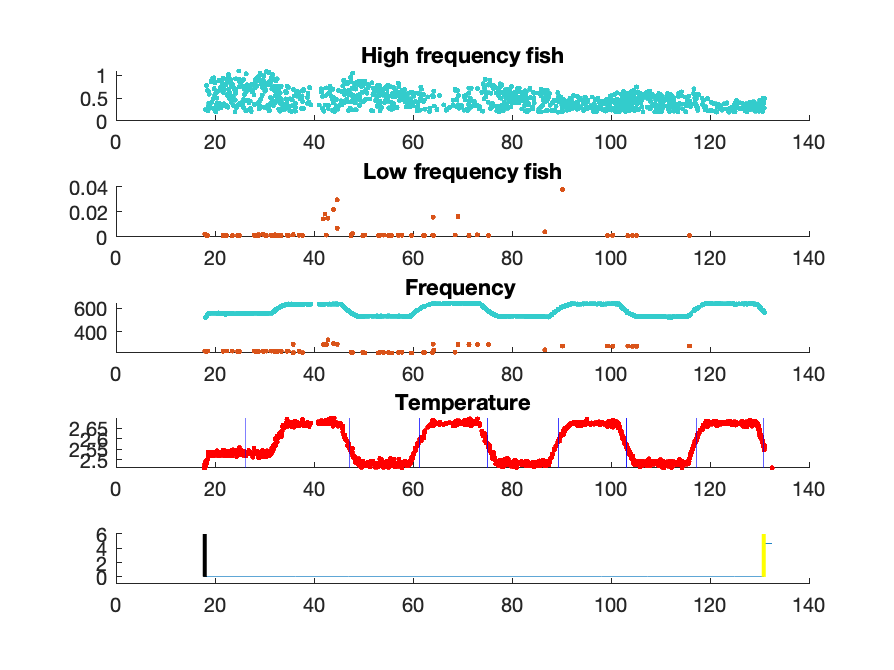

k_multifishplotter(kg2(k));

#### Label

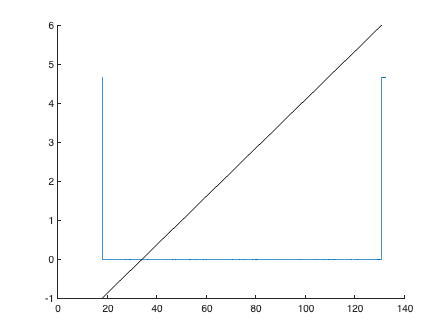

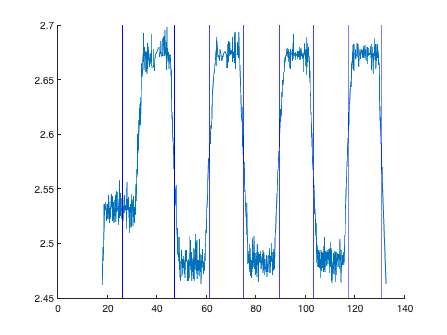

kg2(k).info = KatieMultiLabeler(kg2(k));

kg2(k).info.luz = k_manuallightlabeler(kg2(k));

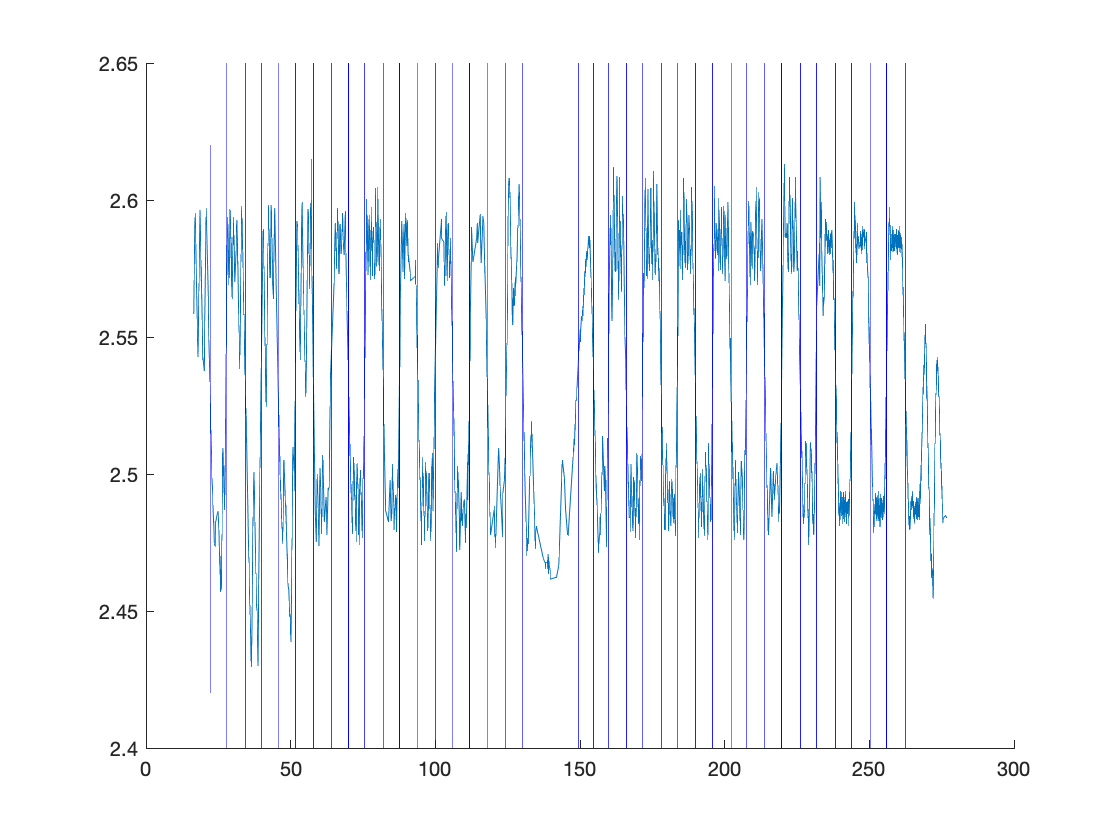

kg2(k).info.temptims = k_templines(kg2(k));

tidx = find(kg2(k).info.temptims < 165);
kg2(k).info.temptims = kg2(k).info.temptims(tidx);

kg2(k).info.luz = kg2(k).info.luz(abs(kg2(k).info.luz) < 165);

kg2(k).info.luz = -(kg2(k).info.luz);

[day] = KatieMultiHIRegobwDayDessembler(in, channel,  ReFs, light)
%% usage

### for when things get messy...

hifish

tube = 1;
fishchunk1idx = find(hi(tube).tim < 228.5);
%     
        for j = 1:length(fishchunk1idx)
           % hi(tube).pkampchunk1(j) = hi(tube).pkamp(fishchunk1idx(j));
            hi(tube).obwampchunk1(j) = hi(tube).obwamp(fishchunk1idx(j))/1.1;
            
            hi(tube).timchunk1(j) = hi(tube).tim(fishchunk1idx(j));

        end

 fishchunk2idx = find(hi(tube).tim >= 115);

%     
        for j = 1:length(fishchunk2idx)
         %   hi(tube).pkampchunk2(j) = hi(tube).pkamp(fishchunk2idx(j))*2;
            hi(tube).obwampchunk2(j) = hi(tube).obwamp(fishchunk2idx(j))*1.1;
            
            hi(tube).timchunk2(j) = hi(tube).tim(fishchunk2idx(j));
        end
        


%save calibration
% hi(tube).pkamp = [hi(tube).pkampchunk1, hi(tube).pkampchunk2];
 hi(tube).obwamp = [hi(tube).obwampchunk1, hi(tube).obwampchunk2];%, hi(tube).obwampchunk3, hi(tube).obwampchunk4];
 hi(tube).tim = [hi(tube).timchunk1, hi(tube).timchunk2];%, hi(tube).timchunk3, hi(tube).timchunk4];
kg2(k).hifish = KatieFinalfishsplit(hi);
 

We are here for k = 18... need final 398 multiplyier... fucking plots

tube = 1;
fishchunk1idx = find(hi(tube).tim < 228.5);
%     
        for j = 1:length(fishchunk1idx)
         
            hi(tube).obwampchunk1(j) = hi(tube).obwamp(fishchunk1idx(j));
            
       
        end

 fishchunk2idx = find(hi(tube).tim >= 228.5 & hi(tube).tim < 278);

%     
        for j = 1:length(fishchunk2idx)
           % hi(tube).pkampchunk2(j) = hi(tube).pkamp(fishchunk2idx(j))*5;
            hi(tube).obwampchunk2(j) = hi(tube).obwamp(fishchunk2idx(j))/7;
            
           % hi(tube).timchunk2(j) = hi(tube).tim(fishchunk2idx(j));
        end
        
 fishchunk3idx = find(hi(tube).tim >=  278);

%     
        for j = 1:length(fishchunk3idx)
        
            hi(tube).obwampchunk3(j) = hi(tube).obwamp(fishchunk3idx(j));
            
       
        end
               




%save calibration
% hi(tube).pkamp = [hi(tube).pkampchunk1, hi(tube).pkampchunk2, hi(tube).pkampchunk3];
 hi(tube).obwamp = [hi(tube).obwampchunk1, hi(tube).obwampchunk2, hi(tube).obwampchunk3];
% hi(tube).tim = [hi(tube).timchunk1, hi(tube).timchunk2, hi(tube).timchunk3];
kg2(k).hifish = KatieFinalfishsplit(hi);
 

tube = 1;


fishchunk1idx = find(lo(tube).tim < 100);
%     
        for j = 1:length(fishchunk1idx)
            %lo(tube).pkampchunk1(j) = lo(tube).pkamp(fishchunk1idx(j))/1.5;
            lo(tube).obwampchunk1(j) = lo(tube).obwamp(fishchunk1idx(j))*1.5;
            
            lo(tube).timchunk1(j) = lo(tube).tim(fishchunk1idx(j));

        end

 fishchunk2idx = find(lo(tube).tim >= 160.2);
%     
        for j = 1:length(fishchunk2idx)
         %   lo(tube).pkampchunk2(j) = lo(tube).pkamp(fishchunk2idx(j));
            lo(tube).obwampchunk2(j) = lo(tube).obwamp(fishchunk2idx(j))*1.75;
            
            lo(tube).timchunk2(j) = lo(tube).tim(fishchunk2idx(j));
        end
        
%save calibration
% lo(tube).pkamp = [lo(tube).pkampchunk1, lo(tube).pkampchunk2];
 lo(tube).obwamp = [lo(tube).obwampchunk1, lo(tube).obwampchunk2];
 lo(tube).tim = [lo(tube).timchunk1, lo(tube).timchunk2];
kg2(k).lofish = KatieFinalfishsplit(lo);  

tube = 1;


fishchunk1idx = find(lo(tube).tim < 100);
%     
        for j = 1:length(fishchunk1idx)
          %  lo(tube).pkampchunk1(j) = lo(tube).pkamp(fishchunk1idx(j));
            lo(tube).obwampchunk1(j) = lo(tube).obwamp(fishchunk1idx(j))*1.5;
            
            lo(tube).timchunk1(j) = lo(tube).tim(fishchunk1idx(j));

        end

 fishchunk2idx = find(lo(tube).tim >= 100 & lo(tube).tim < 365);
%     
        for j = 1:length(fishchunk2idx)
          %  lo(tube).pkampchunk2(j) = lo(tube).pkamp(fishchunk2idx(j))*8.5;
            lo(tube).obwampchunk2(j) = lo(tube).obwamp(fishchunk2idx(j));
            
            lo(tube).timchunk2(j) = lo(tube).tim(fishchunk2idx(j));
        end
        

  fishchunk3idx = find(lo(tube).tim >=  365);
%     
        for j = 1:length(fishchunk3idx)
          %  lo(tube).pkampchunk3(j) = lo(tube).pkamp(fishchunk3idx(j));
            lo(tube).obwampchunk3(j) = lo(tube).obwamp(fishchunk3idx(j))/6.5;
            
            lo(tube).timchunk3(j) = lo(tube).tim(fishchunk3idx(j));
        end      
%save calibration
 %lo(tube).pkamp = [lo(tube).pkampchunk1, lo(tube).pkampchunk2, lo(tube).pkampchunk3];
 lo(tube).obwamp = [lo(tube).obwampchunk1, lo(tube).obwampchunk2, lo(tube).obwampchunk3];
 lo(tube).tim = [lo(tube).timchunk1, lo(tube).timchunk2, lo(tube).timchunk3];
kg2(k).lofish = KatieFinalfishsplit(lo);  

%check
k_fishcalchecker(hi, kg2(k).s,'high frequency fish', tube);

%save calibration
 hi(tube).pkamp = [hi(tube).pkampchunk1, hi(tube).pkampchunk2];
 hi(tube).obwamp = [hi(tube).obwampchunk1, hi(tube).obwampchunk2];
 hi(tube).tim = [hi(tube).timchunk1, hi(tube).timchunk2];

lowfish

tube = 2;
in = hi;

fishchunk1idx = find(in(tube).tim < 126);
    
    in(tube).pkampchunk1 = in(tube).pkamp(fishchunk1idx)*3.5;
    in(tube).obwampchunk1 = in(tube).obwamp(fishchunk1idx)*3.5;


fishchunk2idx = find(in(tube).tim >= 126);

    in(tube).pkampchunk2 = in(tube).pkamp(fishchunk2idx)*1.75;
    in(tube).obwampchunk2 = in(tube).obwamp(fishchunk2idx)*1.75;  

 in(tube).pkamp = [in(tube).pkampchunk1, in(tube).pkampchunk2];
 in(tube).obwamp = [in(tube).obwampchunk1, in(tube).obwampchunk2];




hi = in;

tube = 1;
in = lo;

fishchunk1idx = find(in(tube).tim < 111);
    
    in(tube).pkampchunk1 = in(tube).pkamp(fishchunk1idx)*3;
    in(tube).obwampchunk1 = in(tube).obwamp(fishchunk1idx)*3;


fishchunk2idx = find(in(tube).tim >= 111);

    in(tube).pkampchunk2 = in(tube).pkamp(fishchunk2idx)*1.5;
    in(tube).obwampchunk2 = in(tube).obwamp(fishchunk2idx)*1.5;  

 in(tube).pkamp = [in(tube).pkampchunk1, in(tube).pkampchunk2];
 in(tube).obwamp = [in(tube).obwampchunk1, in(tube).obwampchunk2];




lo = in;


